## Problem Symetical Shortcircuit 7

The bus impedance matrix (Zbus) of a four-bus network with values in per unit is:

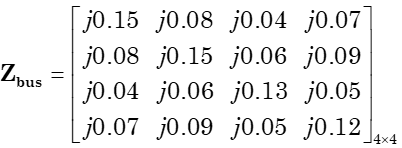

 Generators connected to buses ① and ② have their subtransient reactances included in Zbus. If prefault current is neglected, find the subtransient current in per unit in the fault for a three-phase fault on bus ④. Assume the voltage at the fault is Vf = 1.0<0 per unit before the fault occurs. Find also the per unit current from generator 2 whose subtransient reactance is X”2 = 0.2 per unit.

clear all
clc

The bus impedance matrix (Zbus) of a four-bus network with values in per unit is

Z=[0.15 0.08 0.04 0.04;
    0.08 0.15 0.06 0.09;
    0.04 0.06 0.13 0.05;
    0.07 0.09 0.05 0.12;]*i

Z =    0.0000 + 0.1500i   0.0000 + 0.0800i   0.0000 + 0.0400i   0.0000 + 0.0400i
   0.0000 + 0.0800i   0.0000 + 0.1500i   0.0000 + 0.0600i   0.0000 + 0.0900i
   0.0000 + 0.0400i   0.0000 + 0.0600i   0.0000 + 0.1300i   0.0000 + 0.0500i
   0.0000 + 0.0700i   0.0000 + 0.0900i   0.0000 + 0.0500i   0.0000 + 0.1200i


Vf = 1.0

Vf = 1

The fault current at bus ④ (*I”**cc,4*) is calculated using the Ohm’s law as

k = 4;
If = Vf /Z(k,k);
fprintf(' Icc = (%5.5f < %5.5f) pu', abs(If),angle(If)*180/pi)

 Icc = (8.33333 < -90.00000) pu

fprintf(' Icc = %5.5f + j%5.5f pu', real(If),imag(If))

 Icc = 0.00000 + j-8.33333 pu

Now, the voltage of the bus is ② when the bus is faulted calculated based on:

% Interested bus
j = 2;
V2 = Vf - Z(j,k)/Z(k,k);
fprintf(' V2 = (%5.5f < %5.5f) pu', abs(V2),angle(V2)*180/pi)

 V2 = (0.25000 < 0.00000) pu

fprintf(' V2 = %5.5f + j%5.5f pu', real(V2),imag(V2))

 V2 = 0.25000 + j0.00000 pu

From generator 2, 

Zg2 = 0.2*i;
k = 4;
j = 4;
I2 = (Vf - V2 )/Zg2;
fprintf(' I2 = (%5.5f < %5.5f) pu', abs(I2),angle(I2)*180/pi)

 I2 = (3.75000 < -90.00000) pu

fprintf(' I2 = %5.5f + j%5.5f pu', real(I2),imag(I2))

 I2 = 0.00000 + j-3.75000 pu